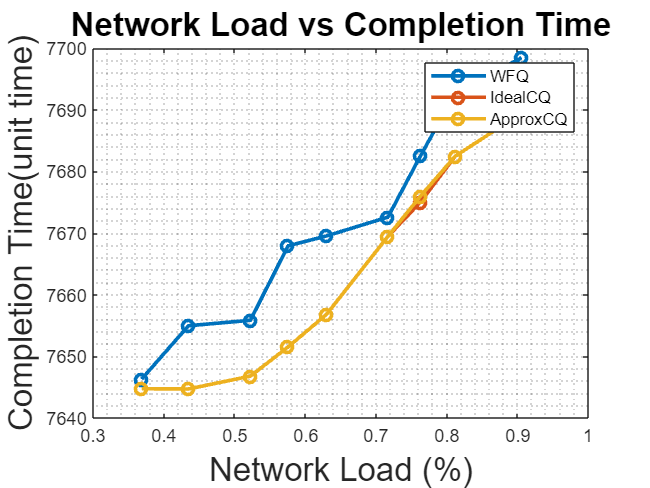

load_values =               [0.3681 0.4343 0.522 0.5751 0.6295 0.7164 0.7624 0.8114 0.9054];
fifo_completion_time =      [7644.74 7644.72 7646.72 7651.42 7656.76 7939.50 8015.25 8693.27 9312.06];
wfq_completion_time =       [7646.26 7654.93 7655.82 7667.91 7669.52 7672.58 7682.52 7692.67 7698.48];
idealCQ_completion_time =   [7644.70 7644.66 7646.75 7651.48 7656.77 7669.45 7675.02 7682.45 7689.52];
approxCQ_completion_time =  [7644.70 7644.66 7646.75 7651.48 7656.77 7669.45 7675.98 7682.45 7689.52];

fifo_utilizitaion =         [100 99.9 99.9 99.9 99.9 99.9 94.4 87.2 79.4];
wfq_utilizitaion =          [100 99.9 99.9 99.9 99.9 99.9 99.9 99.8 99.9];
idealCQ_utilizitaion =      [100 99.9 99.9 99.9 99.9 99.9 99.9 99.8 99.9];
approxCQ_utilizitaion =     [100 99.9 99.9 99.9 99.9 99.9 99.9 99.8 100];

fifo_delay =                [5659.6 10122.6 15661.4 24863   41430.7 126035  293434 532939 868252];
approxCQ_delay =            [5318.9 7764.1  10152.7 13389.9 15973.5 22382.5 26219  29194 38412];
idealCQ_delay =             [5333.6 7847.59 10184.5 13433.5 16146.2 22903   26707  29457 38183];
wfq_delay =                 [4581.7 6725.18 8698.34 11689.7 12912.9 16937   19033  21501 30974];

% Plotting
figure;
grid minor
plot(load_values, wfq_completion_time, '-o', 'DisplayName', 'WFQ',"LineWidth",2);
hold on;
plot(load_values, idealCQ_completion_time, '-o', 'DisplayName', 'IdealCQ',"LineWidth",2);
plot(load_values, approxCQ_completion_time, '-o', 'DisplayName', 'ApproxCQ',"LineWidth",2);
title('Network Load vs Completion Time','FontSize',18);
xlabel('Network Load (%)','FontSize',18);
ylabel('Completion Time(unit time)','FontSize',18);
legend;
hold off

% Load vs Completion Time
grid minor

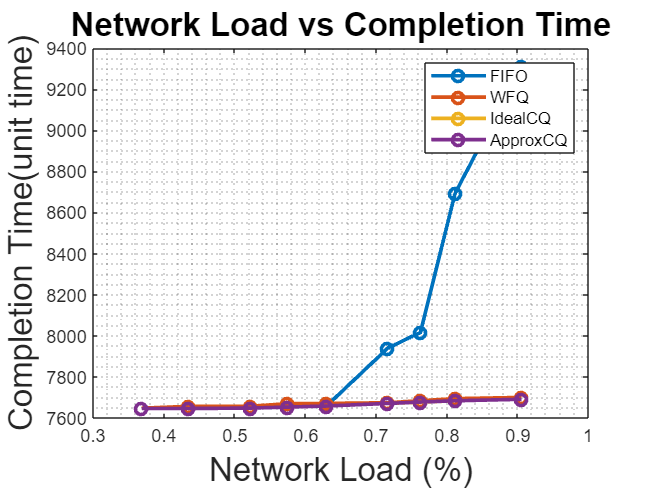

plot(load_values, fifo_completion_time, '-o', 'DisplayName', 'FIFO',"LineWidth",2);
hold on;
plot(load_values, wfq_completion_time, '-o', 'DisplayName', 'WFQ',"LineWidth",2);
hold on;
plot(load_values, idealCQ_completion_time, '-o', 'DisplayName', 'IdealCQ',"LineWidth",2);
plot(load_values, approxCQ_completion_time, '-o', 'DisplayName', 'ApproxCQ',"LineWidth",2);
title('Network Load vs Completion Time','FontSize',18);
xlabel('Network Load (%)','FontSize',18);
ylabel('Completion Time(unit time)','FontSize',18);
legend;
hold off
% Load vs Utilization
grid minor

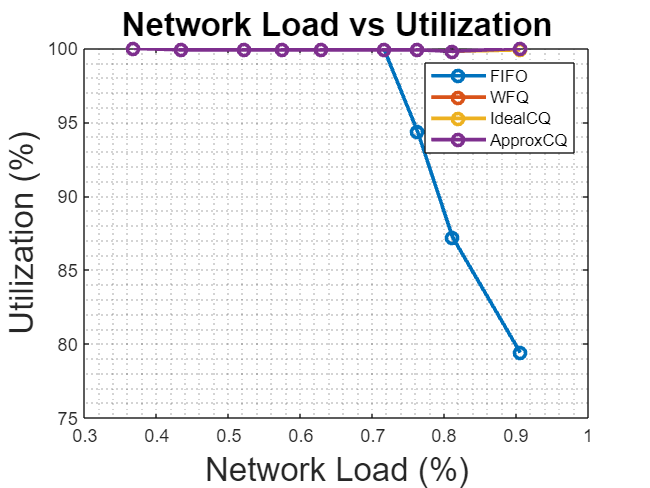

plot(load_values, fifo_utilizitaion, '-o', 'DisplayName', 'FIFO',"LineWidth",2);
hold on;
plot(load_values, wfq_utilizitaion, '-o', 'DisplayName', 'WFQ',"LineWidth",2);
plot(load_values, idealCQ_utilizitaion, '-o', 'DisplayName', 'IdealCQ',"LineWidth",2);
plot(load_values, approxCQ_utilizitaion, '-o', 'DisplayName', 'ApproxCQ',"LineWidth",2);
title('Network Load vs Utilization','FontSize',18);
xlabel('Network Load (%)','FontSize',18);
ylabel('Utilization (%)','FontSize',18);
legend;
hold off
% Load vs Delay
grid minor

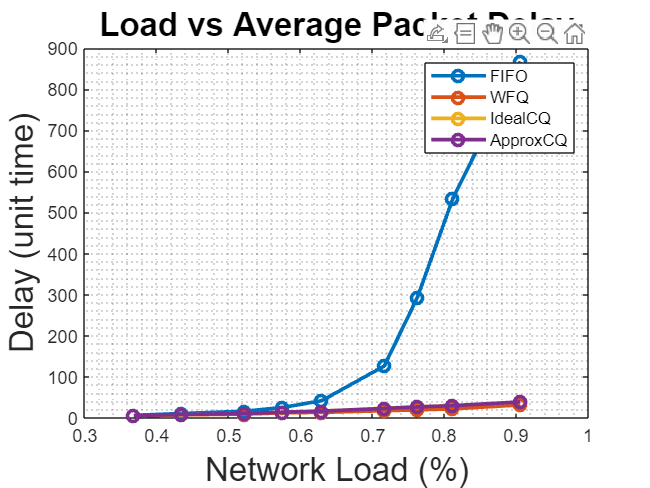

plot(load_values, fifo_delay/1000, '-o', 'DisplayName', 'FIFO',"LineWidth",2);
hold on
plot(load_values, wfq_delay/1000, '-o', 'DisplayName', 'WFQ',"LineWidth",2);

plot(load_values, idealCQ_delay/1000, '-o', 'DisplayName', 'IdealCQ',"LineWidth",2);
plot(load_values, approxCQ_delay/1000, '-o', 'DisplayName', 'ApproxCQ',"LineWidth",2);
title('Load vs Average Packet Delay','FontSize',18);
xlabel('Network Load (%)','FontSize',18);
ylabel('Delay (unit time)','FontSize',18);
legend;
hold off

fifo_completion_time_normalized = normalize(fifo_completion_time,'range', [7000 ,10000]);
wfq_completion_time_normalized = normalize(wfq_completion_time,'range', [7000 ,10000]);
idealCQ_completion_time_normalized = normalize(idealCQ_completion_time,'range', [7000 ,10000]);
approxCQ_completion_time_normalized = normalize(approxCQ_completion_time, 'range',[7000 ,10000]);
hold off
% Plotting


% Load vs Normalized Completion Time
grid minor

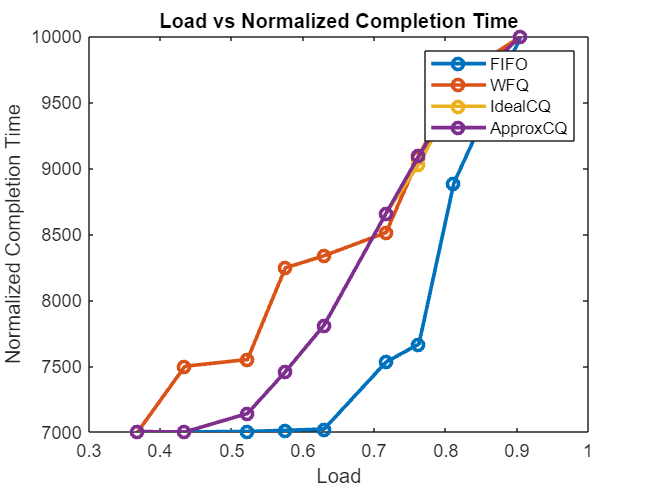

plot(load_values, fifo_completion_time_normalized, '-o', 'DisplayName', 'FIFO',"LineWidth",2);
hold on;
plot(load_values, wfq_completion_time_normalized, '-o', 'DisplayName', 'WFQ',"LineWidth",2);
plot(load_values, idealCQ_completion_time_normalized, '-o', 'DisplayName', 'IdealCQ',"LineWidth",2);
plot(load_values, approxCQ_completion_time_normalized, '-o', 'DisplayName', 'ApproxCQ',"LineWidth",2);
title('Load vs Normalized Completion Time');
xlabel('Load');
ylabel('Normalized Completion Time');
legend;